#  Buzz wire challenge

In the buzz wire game a metal loop is guided along a  wire. The goal is to reach the end terminal of the wire without the loop touching the wire, in which case a buzz noise is heard.

Suppose that the game is played with a robot arm holding the metal loop. This assignment aims at finding a strategy for the robot arm to move as fast as possible from the start to the end terminal of the wire without touching the wire. For simplicity, the following assumptions are considered:

-  The wire lies in a plane with $x$ and $y$ coordinates. Moreover, it can be represented by a function $y=f(x)$ as depicted in the figure below, which implies that it does not curve back.

- The metal loop is represented by two small parallel bars, shown in blue in the figure, which form a rigid body with center point represented by a blue circle in the figure. Both the length of each bars and the space between the two bars are set to $4.1$. The configuration of these parallel linear is characterized by the position of the center point, denoted by $(p_x,p_y)$, and an orientation angle $\theta \in (-\frac{\pi}{2},\frac{\pi}{2})$, which represents a rotation angle with  respect to a frame with origin at the center point; $\theta = 0$ when the two blue bars are parallel to the $x$ axis and $\theta >0$ corresponds to an anti-clockwise rotation. The metal loop touches the wire if one of these parallel bars intersects the wire. This check is performed for a finite set of points of the bottom and top bars.

- The space is discretized such that each coordinate position of the  center point $(x,y)$ is a natural number, $x \in \{1,2,\dots,N_x\}$, $y \in \{1,2,\dots,N_y\}$ and the angle belongs to the set $\theta \in \{-\frac{\pi}{2}+i\frac{\pi }{N_\theta+1}\}$, for $i \in \{1,2,\dots,N_\theta\}$.

-  The game starts at time $k=1$ with $p_{x,1}=1$ and a feasible configuration where the metal looop does not touch the wire.

-  The game is over when $p_{x,k}=N_x$ for a given $k=K+1$ and there have been no colisions for every $k\leq K+1$. $K$ is the number of steps/times since the inital step/time $k=1$, which should be minimized. 

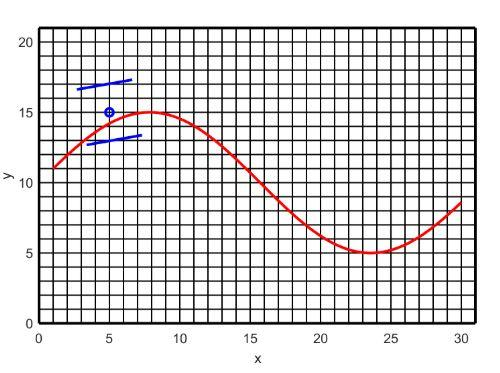

An example of an environment and a test to check if the metal loop touches the wire is given next (you can click on run Section to avoid running the remainder of the Live Script).


clear all
close all
Nx     = 30;
Ny     = 20;
Ntheta = 17;
Mx     = 4;
My     = 5;
Mtheta = 5;
n = Nx*Ny*Ntheta;
m = Mx*My*Mtheta;
deltawire = 0.1;
x_ = 1:deltawire:Nx; wirefunction = 10*ones(size(x_))+5*sin(0.2*x_);
tmetal = plotenvironment(Nx,Ny,Ntheta,wirefunction);
metaltoucheswire(5,15,10,Nx,Ntheta,wirefunction)

ans = 0

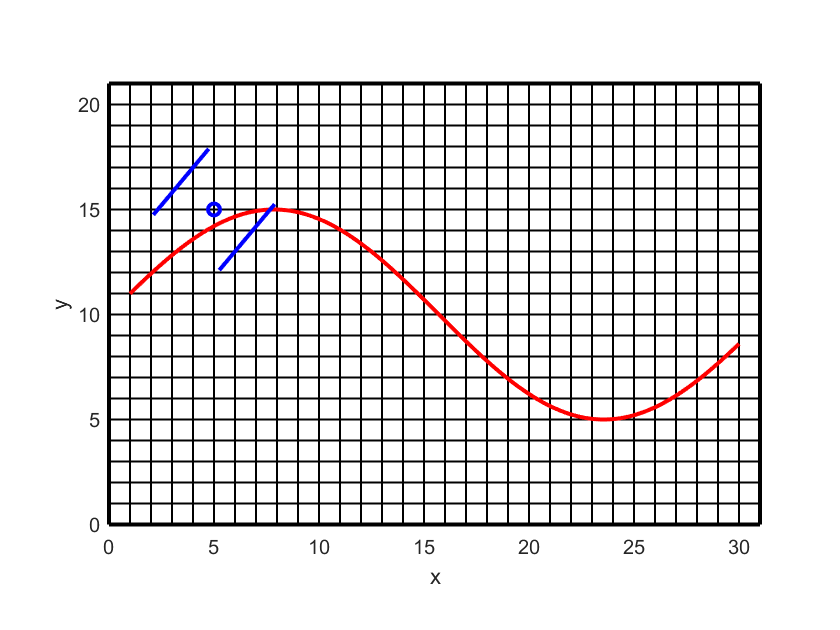

plotmetal([5 15 14],tmetal,Ntheta)

metaltoucheswire(5,15,14,Nx,Ntheta,wirefunction)

ans = 1

## Deterministic model

A purely kinematic model for the robot holding the metal loop is considered and it is assumed that the joint angles are such that the robot can reach all the configurations of interest, therefore (using the robot kinematics) we can assume that $x$, $y$, and $\theta$ can be controlled directly. The following discrete-time model is considered

            
$$$$  p_{x,k+1} =\min\{\max\{p_{x,k}+ u_{x,k},1\},N_x\} $$  
 $$


            
$$$$ p_{y,k+1} =\min\{\max\{p_{y,k}+ u_{y,k},1\},N_y \}$$
 $$
           

             
$$$$\theta_{k+1} =\min\{\max\{\theta_k+ \frac{ \pi}{N_\theta+1} u_{\theta,k},-\pi \frac{ (N_\theta-1)/2}{N_\theta+1} \},\pi\frac{ (N_\theta-1)/2}{N_\theta+1} \} \end{aligned}$$$$


            with $u_{x,k}\in \{0,1,\dots,M_x-1\}$,   $u_{y,k}\in \{-(M_y-1)/2,-(M_y-1)/2+1,\dots,(M_y-1)/2\}$, $u_{\theta,k}\in \{-(M_\theta-1)/2,-(M_\theta-1)/2+1,\dots,(M_\theta-1)/2\}$ for odd $M_y$ and $M_\theta$.

## Stochastic model

A more advanced stochastic model can specify that even if an action tries to enforce that the metal loop arrives at a given configuration, this might not be the case due to disturbances. Disturbances are assumed to only change the position and not the angle. The exact discrete time model considered is the following


$$$$  p_{x,k+1} =\min \{\max\{p_{x,k}+ u_{x,k}+d_{x,k},1\},N_x\} $$$$



$$$$ p_{y,k+1} =\min\{\max\{p_{y,k}+ u_{y,k}+d_{y,k},1\},N_y \}$$$$



$$$$\theta_{k+1} =\min\{\max\{\theta_k+ \frac{ \pi}{N_\theta+1} u_{\theta,k},-\pi \frac{ (N_\theta-1)/2}{N_\theta+1} \},\pi\frac{ (N_\theta-1)/2}{N_\theta+1} \} \end{aligned}$$$$


where $$d_{x,k} \in \{-1,0,1\}$$ and $$d_{y,k}\in \{-1,0,1\}$$. The probabilities of all the possible events are summarized in a vector $$p = [p_1 \; p_2 \, p_3 \,\dots p_9]$$ 


$$$$ \text{Prob}[(d_{x,k},d_{y,k})=c_i]=p_i, i \in \{1,\dots,9\},$$$$


with $c_1=(-1,1)$, $c_2=(0,1)$, $c_3=(1,1)$, $c_4=(-1,0)$, $c_5=(0,0)$, $c_6=(1,0)$, $c_7=(-1,-1)$, $c_8=(0,-1)$, $c_9=(1,-1)$.

 Since the model is stochastic it might be the case that  collisions do occur, even if uninteded (i.e., these would not occur if $(d_{x,k},d_{y,k})=(0,0)$ ). If a collision occurs the game stops and a typically large positive penalty $C_W$ is incurred. Note that if the metal wire is far from the end goal it might be optimal to hit the wire (or risk to hit it) and incur a penaly CW instead of incurring in a penalty coincinding with the time to reach the end.

**Implementation**

The following script allows to visualize the behavior of the dynamic programming (stochflag = 0) and stochastic dynamic programming (stochflag = 1) policies for the parameters given above (note that these will not work if the parameters are changed). Note that the optimal policies and optimal paths are not unique (only the costs-to-go and optimal number of steps are unique) and therefore your implementation might and in general will lead to a different path. 

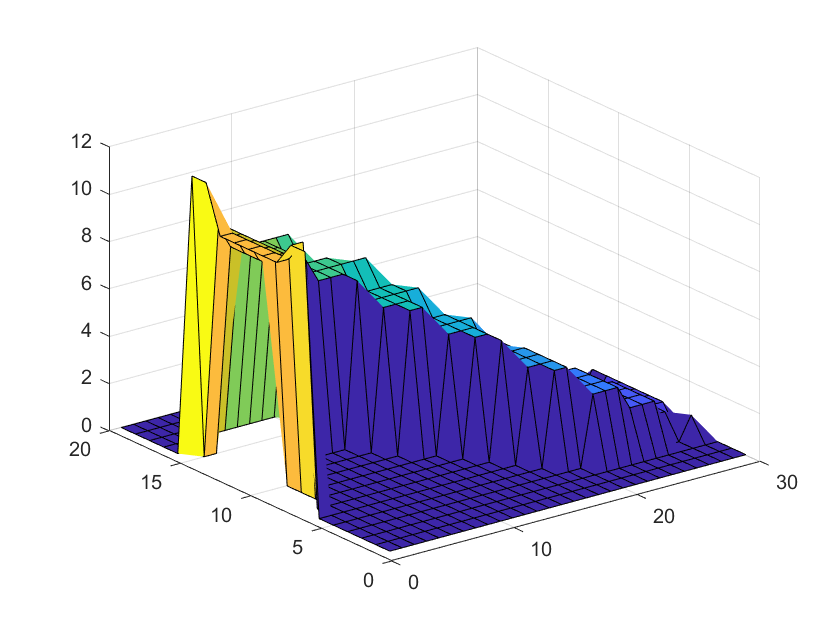

stochflag = 0; % 0 DP, 1 -Stoch DP
if stochflag == 1
    CW = 14;
    p  = [0.04 0.12 0.04 0.12 0.36 0.12 0.04 0.12 0.04];
    [mu,J] = buzzwiredpstoch(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,CW,p);
else
    [mu,J] = buzzwiredp(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction);
end
% optimal time (only for deterministic dp
x0 = [1 10 14];
T  = J(x0(1),x0(2),x0(3));

[X,Y]   = meshgrid(1:Nx,1:Ny);
J_2     = inf*ones(Ny,Nx);
for ix = 1:Nx
    for iy = 1:Ny
        J_2(iy,ix) = min(J(ix,iy,:));
    end
end
J_2(J_2 == inf) = 0;
figure(11)
surf(X,Y,J_2)

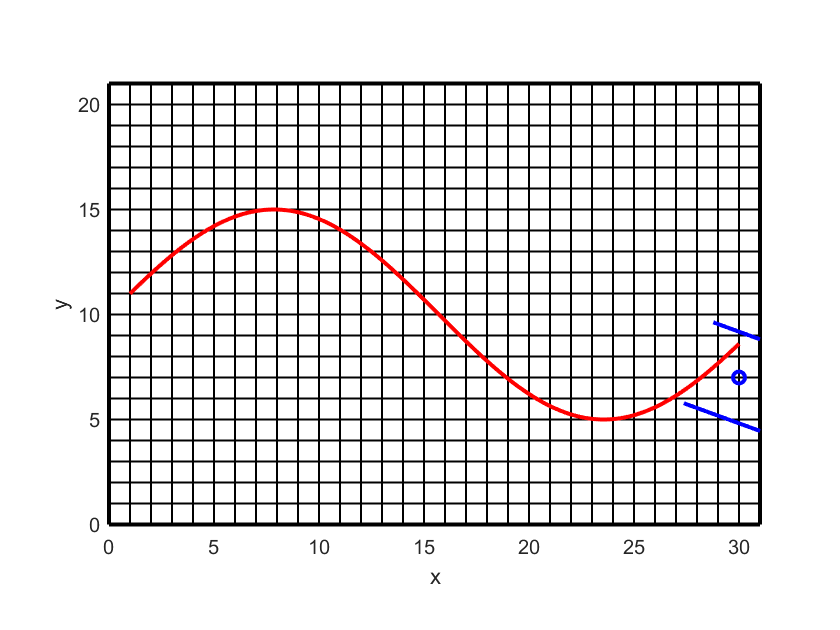


% animation
x(:,1)  = x0;
tmetal = plotenvironment(Nx,Ny,Ntheta,wirefunction);
k = 1;
while(1)
    plotmetal([x(1,k) x(2,k) x(3,k)],tmetal,Ntheta);
    pause(0.3)
    u(:,k)         = mu{x(1,k)}{x(2,k)}{x(3,k)};
    x(1,k+1)       = min(x(1,k)+u(1,k),Nx);
    x(2,k+1)       = min(max(x(2,k)+u(2,k),1),Ny);
    x(3,k+1)       = min(max(x(3,k)+u(3,k),1),Ntheta);
    if x(1,k+1) == Nx
        break
    end
    k = k+1;
end
plotmetal([x(1,k+1) x(2,k+1) x(3,k+1)],tmetal,Ntheta);

The following code allows you to check the behavior of the Dijkstra's algorithm.

x0            = [1 10 14];
[optpath] = buzzwiredijkstra(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,x0);

figure
tmetal2          = plotenvironment(Nx,Ny,Ntheta,wirefunction);


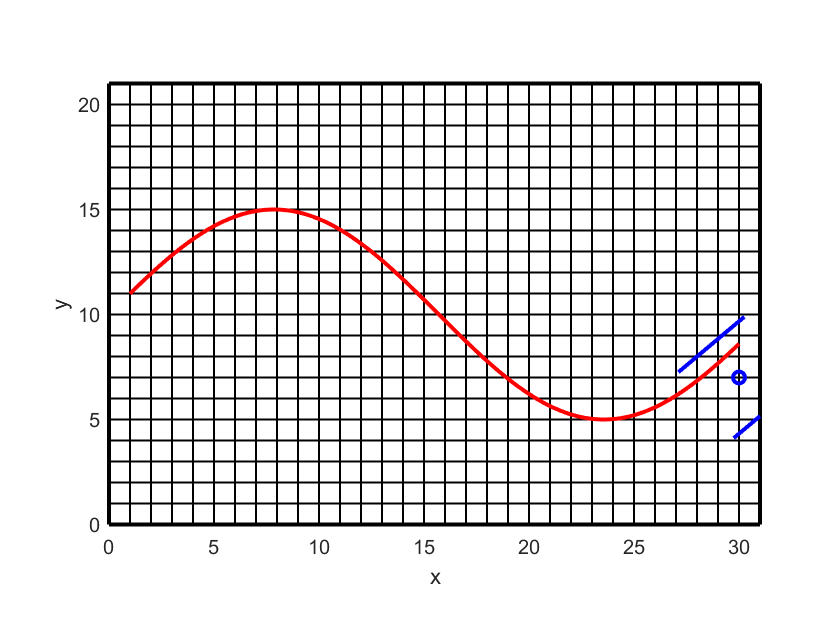

Toptpath      = size(optpath,1);
for k = 1:Toptpath
    plotmetal([optpath(k,1) optpath(k,2) optpath(k,3)],tmetal2,Ntheta);
    pause(0.3)
end

This function plots the environment and output a handler for the metal object to be used by other functions.

function tmetal = plotenvironment(Nx,Ny,Ntheta,wirefunction)
deltawire  = (Nx-1)/(length(wirefunction)-1);
spacingfingers = 4.1;
d  = spacingfingers/2;
plot( [0 0],[0 Ny+1],"LineWidth",2,"Color",[0 0 0])
hold on
plot( [Nx+1 Nx+1],[0 Ny+1],"LineWidth",2,"Color",[0 0 0])
for ix = 1:Nx
    plot( [ix ix],[0 Ny+1],"LineWidth",1,"Color",[0 0 0])
end
for iy = 1:Ny
    plot([0 Nx+1],[iy iy],"LineWidth",1,"Color",[0 0 0])
end
plot([0 Nx+1],[0 0],"LineWidth",2,"Color",[0 0 0])
plot([0 Nx+1],[Ny+1 Ny+1],"LineWidth",2,"Color",[0 0 0])
axis equal
axis([0 Nx+1 0 Ny+1])
x_ = 1:deltawire:Nx; plot(x_,wirefunction,"LineWidth",2,"Color",[1 0 0])
tfinger1 = line([-d d],[d d],"LineWidth",2,"Color",[0 0 1]);
tfinger2 = line([-d d],[-d -d],"LineWidth",2,"Color",[0 0 1]);
tcircle  = plot(0,0,'o',"LineWidth",2,"Color",[0 0 1]);
tmetal = hgtransform('Parent',gca);
set(tfinger1,'parent',tmetal);
set(tfinger2,'parent',tmetal);
set(tcircle,'parent',tmetal);
xlabel('x')
ylabel('y')
plotmetal([5 15 15],tmetal,Ntheta);
end

This functions plots the metal.

function plotmetal(pmetal,tmetal,Ntheta)
itheta     = pmetal(3);
deltatheta = pi/(Ntheta+1);
theta      = itheta*deltatheta-pi/2;
R          = [cos(theta) -sin(theta) 0;sin(theta) cos(theta) 0; 0 0 1];
P          = [pmetal(1) pmetal(2) 0]';
Tmetal     = [ R  P; zeros(1,3) 1];
set(tmetal,'Matrix',Tmetal)
end


The following four functions are auxiliary functions for the algorithms.

function [ix,iy,itheta] = state2coord(i,Ny,Ntheta)
ix     = floor( (i-1)/(Ny*Ntheta))+1;
iy     = floor((i-1-(ix-1)*(Ny*Ntheta))/Ntheta)+1;
itheta = i-(ix-1)*(Ny*Ntheta)-(iy-1)*Ntheta;
end

function [i] = coord2state(ix,iy,itheta,Ny,Ntheta)
i = (ix-1)*Ny*Ntheta + (iy-1)*Ntheta + itheta;
end

function [jx,jy,jtheta] = action2coord(j,My,Mtheta)
jx     = floor( (j-1)/(My*Mtheta))+1;
jy     = floor((j-1-(jx-1)*(My*Mtheta))/Mtheta)+1;
jtheta = j-(jx-1)*(My*Mtheta)-(jy-1)*Mtheta;
end

function [j] = coord2action(jx,jy,jtheta,My,Mtheta)
j = (jx-1)*My*Mtheta + (jy-1)*Mtheta + jtheta;
end


The follwoing is a key function determining when the metal touches the wire.

function [boolean] = metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
spacingfingers = 4.1;
deltatheta  = pi/(Ntheta+1);
theta       = itheta*deltatheta-pi/2;
deltawire   = (Nx-1)/(length(wirefunction)-1);
xwire       = ix;
ywire       = wirefunction(round((xwire-1)/deltawire)+1);
if abs(ywire-iy)>spacingfingers
    boolean = 1;
else
    % four corners
    R  = [cos(theta) -sin(theta); sin(theta) cos(theta)];
    d  = spacingfingers/2;
    pu1 = [ix; iy] + R*[-d d]';
    pu2 = [ix; iy] + R*[d d]';
    pl1 = [ix; iy] + R*[-d -d]';
    pl2 = [ix; iy] + R*[d -d]';
    if pu2(1) < 1 || pu1(1) > Nx % if the full metal arm is outside of the environemnt possibly the wire is such that it does not touch
        cu = 1;
    else
        indleftlimu  = round(1+(max(min(pu1(1),Nx),1)-1)/deltawire);
        indrightlimu = round(1+(max(min(pu2(1),Nx),1)-1)/deltawire);
        indtestu     = indleftlimu:indrightlimu;
        for i = 1:length(indtestu)
            xwireu(i)   = 1+(indtestu(i)-1)*deltawire;
            ywireu(i)   = wirefunction(indtestu(i));
            ymetalu(i)   = pu1(2)+ (pu2(2)-pu1(2))/(pu2(1)-pu1(1))*(xwireu(i)-pu1(1));
            cu(i)       = ymetalu(i)-ywireu(i) > 0;
        end
    end
    
    if pl2(1) < 1 || pl1(1) > Nx
        cl = 1;
    else
        indleftliml  = round(1+(max(min(pl1(1),Nx),1)-1)/deltawire);
        indrightliml = round(1+(max(min(pl2(1),Nx),1)-1)/deltawire);
        indtestl     = indleftliml:indrightliml;
        for i = 1:length(indtestl)
            xwirel(i)   = 1+(indtestl(i)-1)*deltawire;
            ywirel(i)   = wirefunction(indtestl(i));
            ymetall(i)   = pl1(2)+ (pl2(2)-pl1(2))/(pl2(1)-pl1(1))*(xwirel(i)-pl1(1));
            cl(i)       = ymetall(i)-ywirel(i) < 0;
        end
    end
    
    if all(cu == 1) & all(cl == 1)
        boolean = 0;
    else
        boolean = 1;
    end
    
end

end

The following function solved the buzz wire problem with dynamic programming.

function [mu,J] = buzzwiredp(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,flag)
if nargin == 7
    flag = 0;
end

n = Nx*Ny*Ntheta;
m = Mx*My*Mtheta;

D  = zeros(n,m);
C  = zeros(n,m);
Jh = inf*ones(n,1);
for i = 1:n
    [ix,iy,itheta] = state2coord(i,Ny,Ntheta);
    % terminal cost
    if ix == Nx
        if ~metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
            Jh(i) = 0;
            C(i,:) = 0;
            D(i,:) = i;
        else
            Jh(i) = inf;
            C(i,:) = inf;
            D(i,:) = i;
        end
    else
        if metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
            C(i,:) = inf;
            D(i,:) = i;
        else
            for j = 1:m
                C(i,j)    = 1;
                D(i,j)    = nextstate(i,j,Nx,Ny,Ntheta,Mx,My,Mtheta);
            end
        end
    end
end
[mu_,J_] = dpsp( D, C, Jh);

J  = zeros(Nx,Ny,Ntheta);

for i = 1:n
    [ix,iy,itheta]    = state2coord(i,Ny,Ntheta);
    J(ix,iy,itheta)   = J_(i);
    if flag == 0
        [jx,jy,jtheta]     = action2coord(mu_{i}(1),My,Mtheta);
        mu{ix}{iy}{itheta} = [jx-1,jy-(My-1)/2-1,jtheta-(Mtheta-1)/2-1];
    else
        for j = 1:length(mu_{i})
            [jx,jy,jtheta]       = action2coord(mu_{i}(j),My,Mtheta);
            mu{ix}{iy}{itheta}(j,1:3) = [jx-1,jy-(My-1)/2-1,jtheta-(Mtheta-1)/2-1];
        end
    end
end

end


The following function solves the buzz wire problem with uncertainty with stochastic dynamic programming.

function [mu,J] = buzzwiredpstoch(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,CW,p,flag)
if nargin == 9
    flag = 0;
end

np = length(p);
pcases = [-1 1;
    0 1;
    1 1;
    -1 0;
    0 0;
    1 0;
    -1 -1;
    0 -1;
    1 -1];
n = Nx*Ny*Ntheta;
m = Mx*My*Mtheta;
D  = zeros(n+1,m,np);
C  = zeros(n+1,m);
Jh      = inf*ones(n+1,1);
Jh(n+1) = 0;

for i = 1:n
    [ix,iy,itheta] = state2coord(i,Ny,Ntheta);
    % terminal cost
    if ix == Nx
        if ~metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
            Jh(i) = 0;
            C(i,:) = 0;
            D(i,:,:) = n+1;
        else
            Jh(i) = inf;
            C(i,:) = inf;
            D(i,:,:) = n+1;
        end
    else
        if metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
            C(i,:)   = CW;
            D(i,:,:) = n+1;
        else
            for j = 1:m
                C(i,j)    = 1;
                for ell = 1:np
                    [ix,iy,itheta] = state2coord(i,Ny,Ntheta);
                    [jx,jy,jtheta] = action2coord(j,My,Mtheta);
                    ix_1       = min(max(ix+(jx-1)+pcases(ell,1),1),Nx);
                    iy_1       = min(max(iy+jy-(My-1)/2-1+pcases(ell,2),1),Ny);
                    itheta_1   = min(max(itheta+jtheta-(Mtheta-1)/2-1,1),Ntheta);
                    D(i,j,ell) = coord2state(ix_1,iy_1,itheta_1,Ny,Ntheta);
                end
            end
        end
    end
end
D(n+1,:) = n+1;
C(n+1,:) = 0;

[mu_,J_] = dpspstoch( D, C, p, Jh);

J  = zeros(Nx,Ny,Ntheta);

for i = 1:n
    [ix,iy,itheta]    = state2coord(i,Ny,Ntheta);
    J(ix,iy,itheta)   = J_(i);
    if flag == 0
        [jx,jy,jtheta]     = action2coord(mu_{i}(1),My,Mtheta);
        mu{ix}{iy}{itheta} = [jx-1,jy-(My-1)/2-1,jtheta-(Mtheta-1)/2-1];
    else
        for j = 1:length(mu_{i})
            [jx,jy,jtheta]       = action2coord(mu_{i}(j),My,Mtheta);
            mu{ix}{iy}{itheta}(j,1:3) = [jx-1,jy-(My-1)/2-1,jtheta-(Mtheta-1)/2-1];
        end
    end
end

end


The following function solves the buzz wire deterministic problem with the Dijkstra's algorithm.

function [optconfpath,optstateindex,decT] = buzzwiredijkstra(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,x0)

inode    = coord2state(x0(1),x0(2),x0(3),Ny,Ntheta);
nmax     = Nx*Ny*Ntheta;          % max number of nodes
m        = Mx*My*Mtheta;
openT    = [zeros(nmax,1) inf*ones(nmax,1) zeros(nmax,1)]; % prealocate memory
decT     = zeros(1,nmax);           % simply to keep track of optimal decisions, not necesary for the algorithm
nopenT   = 1;                     % number of nodes in openT

openT(1,:) = [inode 0 -1];        %(node,cost-to-come to inode,prev. node)
closedT    = [zeros(nmax,1) inf*ones(nmax,1) zeros(nmax,1)]; % prealocate memory
nclosed    = 0;                         % number of nodes in closedT


while(1)
    % shortest distance -(cur)node, add to closed, stop if terminal
    [~,curnodeind]     = min(openT(:,2));
    curnode            = openT(curnodeind,1);
    curnodecost        = openT(curnodeind,2);
    nclosed            = nclosed + 1;
    closedT(nclosed,:) = openT(curnodeind,:);
    [ix_,~,~] = state2coord(curnode,Ny,Ntheta);
    if ix_ == Nx
        fnode = curnode;
        break;
    end
    
    % remove curnode from open, move last to its position
    if nopenT > 1
        openT(curnodeind,:) = openT(nopenT,:);
    end
    openT(nopenT,:) = [0 inf 0];
    nopenT = nopenT-1;
    
    % update neighboors of curnode
    % Obtain all valid neighboors that do not touch the wire
    for j = 1:m
        xneigh = nextstate(curnode,j,Nx,Ny,Ntheta,Mx,My,Mtheta);
        if(~any([closedT(:,1) == xneigh])) % if it in closed, skip it
            [ix_2,iy_2,itheta_2] = state2coord(xneigh,Ny,Ntheta);
            if metaltoucheswire(ix_2,iy_2,itheta_2,Nx,Ntheta,wirefunction)
                % in neigh touches the wire put it in the closed list
                nclosed = nclosed+1;
                closedT(nclosed,:) = openT(xneigh,:);
            else
                % if neigh does not touches the wire put it in open list if
                % it is not there already, or otherwise update it
                auxvec = [openT(:,1) == xneigh];
                if( any( auxvec )) % if it is in the open list update
                    indneighopen = find(auxvec);
                    if  curnodecost + 1 < openT(indneighopen,2)
                        openT(indneighopen,2) = curnodecost + 1;
                        openT(indneighopen,3) = curnode;
                        decT(curnode) = j;
                    end
                else % if not, add it to open
                    nopenT = nopenT + 1;
                    openT(nopenT,1) = xneigh;
                    openT(nopenT,2) = curnodecost + 1;
                    openT(nopenT,3) = curnode;
                    decT(curnode) = j;
                end
            end
            
        end
    end
end

[optconfpathx,optconfpathy,optconfpaththeta] = state2coord(fnode,Ny,Ntheta);
optconfpath   = [optconfpathx optconfpathy optconfpaththeta];
optstateindex = fnode;
node = fnode;
while( node ~= inode )
    indnode = find( closedT(:,1) == node);
    node = closedT(indnode,3);
    [optconfpathx,optconfpathy,optconfpaththeta] = state2coord(node,Ny,Ntheta);
    optconfpath   = [[optconfpathx optconfpathy optconfpaththeta];optconfpath];
    optstateindex = [node,optstateindex];
end

end


The following function is an auxiliary function for solving the buzz wire problem with deterministic dynamic programming.

function [u_,J_] = dpsp( M, C, Jh)

[n,~] = size(M);
J = Jh;

J_ = zeros(n,1);
while(1)
    for i = 1:n
        if any(C(i,:) ~=inf)
            [J_(i)]  = min( C(i,:)' + J(M(i,:)) );
        else
            J_(i) = inf;
        end
    end
    if J == J_;
        for i = 1:n
            if any(C(i,:) ~=inf)
                u_{i}       = find(J_(i) == C(i,:)' + J(M(i,:)) );
            else
                u_{i} = 1;
            end
        end
        break
    else
        J = J_;
    end
end
end


The following function is an auxiliary function for solving the buzz wire problem with stochastic dynamic programming.

function [u_,J_] = dpspstoch(M, C, p, Jh)

[n,m,~]  = size(M);
np     = length(p);
J      = Jh;
J_     = zeros(n,1);

while(1)
    for i = 1:n
        if any(C(i,:) ~=inf)
            caux = zeros(1,m);
            for j=1:m
                caux(j) = 0;
                for l=1:np
                    caux(j) = caux(j) + p(l)*(C(i,j) + J(M(i,j,l)));
                end
            end
            [J_(i)] = min( caux );
        else
            J_(i) = inf;
        end
    end
    if J == J_;
        for i = 1:n
            if any(C(i,:) ~=inf)
                caux = zeros(1,m);
                for j=1:m
                    caux(j) = 0;
                    for l=1:np
                        caux(j) = caux(j) + p(l)*(C(i,j) + J(M(i,j,l)));
                    end
                end
                u_{i}       = find(J_(i) == caux );
            else
                u_{i} = 1;
            end
        end
        break
    else
        J = J_;
    end
end
end


The following function determines the next state given the indices characterizing the current state and the control action.

function [i_1] = nextstate(i,j,Nx,Ny,Ntheta,Mx,My,Mtheta)
[ix,iy,itheta] = state2coord(i,Ny,Ntheta);
[jx,jy,jtheta] = action2coord(j,My,Mtheta);
ix_1     = min(ix+(jx-1),Nx);
iy_1     = min(max(iy+jy-(My-1)/2-1,1),Ny);
itheta_1 = min(max(itheta+jtheta-(Mtheta-1)/2-1,1),Ntheta);
i_1 = coord2state(ix_1,iy_1,itheta_1,Ny,Ntheta);
end